clc
clear 

## Primer examen prueba

%uiimport("airports.csv");
t=importfile("flightsJan.csv");
head(t,5)   

ans = 5×24 table
    YEAR    MONTH    DAY_OF_MONTH    OP_CARRIER    TAIL_NUM    OP_CARRIER_FL_NUM    ORIGIN    DEST    CRS_DEP_TIME    DEP_TIME    DEP_DELAY    TAXI_OUT    TAXI_IN    CRS_ARR_TIME    ARR_TIME    ARR_DELAY    CANCELLED    CANCELLATION_CODE    DIVERTED    CRS_ELAPSED_TIME    ACTUAL_ELAPSED_TIME    AIR_TIME    DISTANCE    VarName24
    ____    _____    ____________    __________    ________    _________________    ______    ____    

a=importfile1("airports.csv");


t11=groupsummary(t,"ACTUAL_ELAPSED_TIME");
t11 = sortrows(t11,'ACTUAL_ELAPSED_TIME');
head(t11,5)

ans = 5×2 table
    ACTUAL_ELAPSED_TIME    GroupCount
    ___________________    __________

            17                 5     
            18                 3     
            19                 5     
            20                 5     
            21                 5     


corr(t.ARR_DELAY,t.DEP_DELAY,'rows','complete')

ans = 0.9381

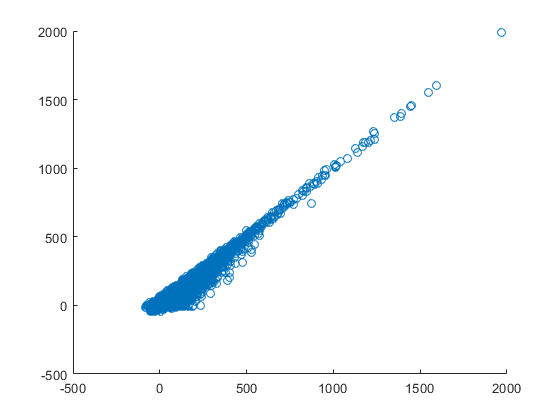

scatter(t.ARR_DELAY,t.DEP_DELAY)

%scatter(t.ARR_DELAY,t.TAXI_OUT);
%scatter(t.ARR_DELAY,t.TAXI_IN);
%scatter(t.ARR_DELAY,t.)


t2=t(t.CANCELLED==1,:);
t2=groupsummary(t2,"CANCELLATION_CODE")

t2 = 4×2 table
    CANCELLATION_CODE    GroupCount
    _________________    __________

           "A"              2874   
           "B"              7020   
           "C"              2087   
           "D"                 1   


%bar(t2.CANCELLATION_CODE,t2.GroupCount)
%xlabel("Code")
%ylabel("Number of cancellations")
%title("January's Cancellations")

y=importfile("flightsAug.csv");
y2=y(y.CANCELLED==1,:);
y2=groupsummary(y2,"CANCELLATION_CODE")

y2 = 4×2 table
    CANCELLATION_CODE    GroupCount
    _________________    __________

           "A"              2364   
           "B"              1310   
           "C"              1376   
           "D"                 2   


## Examen final Primer modulo

t=importfile("flightsJan.csv");
f=groupsummary(t,"ORIGIN");
f = sortrows(f,'GroupCount','descend');
head(f,3)

ans = 5×2 table
    ORIGIN    GroupCount
    ______    __________

     ATL        29512   
     ORD        23484   
     DFW        23153   
     LAX        17340   
     DEN        17090   


f2=groupsummary(t,"ORIGIN","mean","DISTANCE");
f2 = sortrows(f2,'mean_DISTANCE');
head(f2,3)

ans = 3×3 table
    ORIGIN    GroupCount    mean_DISTANCE
    ______    __________    _____________

     WRG          62            56.5     
     PSG          62              77     
     CSG          80              83     


f3=t(t.CANCELLED==1,:);
size(f3)

ans =        11982          24


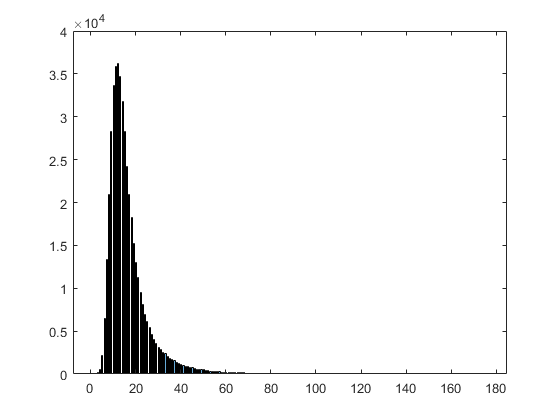

histogram(t.TAXI_OUT)